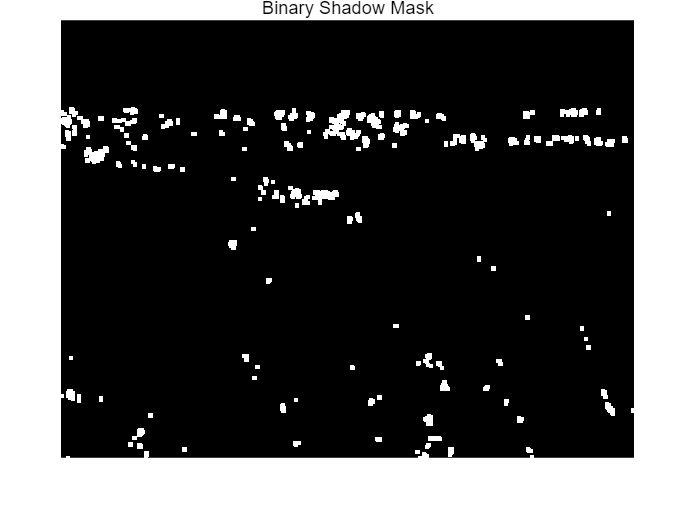

clear;clc;
% 读取图像
or_img = imread('../resources/_MG_2387.jpg');

% 将图像从 RGB 转换为 YCbCr
y_cb_cr_img = rgb2ycbcr(or_img);

% 获取 Y, Cb 和 Cr 通道
y_channel = y_cb_cr_img(:,:,1);  % Y 通道
cb_channel = y_cb_cr_img(:,:,2);  % Cb 通道
cr_channel = y_cb_cr_img(:,:,3);  % Cr 通道

% 创建一个二值掩膜（阴影区域）
binary_mask = y_channel < mean(y_channel(:)) - std(double(y_channel(:)));

% 使用形态学操作来平滑掩膜
se = strel('square', 3);  % 定义一个 6x6 的结构元素
open_mask = imopen(binary_mask, se);  % 开运算去除噪声

% 显示形态学操作后的掩膜
figure;
imshow(open_mask, []);
title('Binary Shadow Mask');

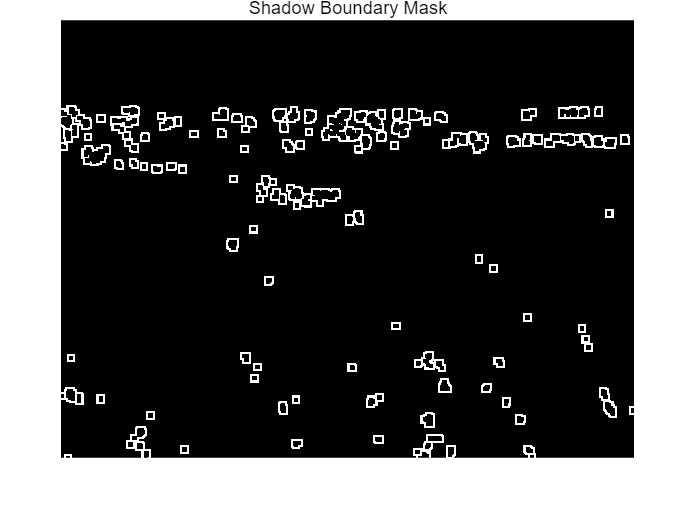

% ------------------------------------------
% 阴影去除：调整阴影区域的亮度和色温
% ------------------------------------------

output_img = double(or_img);  % 转换为 double 类型进行处理

% 获取图像的尺寸
[rows, cols, ~] = size(output_img);

% 将 2D 掩膜扩展为 3D 掩膜，以匹配图像的尺寸
shadow_area = repmat(open_mask, [1, 1, 3]);  % 扩展到三通道的掩膜

% 获取阴影区域的外围区域：膨胀掩膜并取差集
se2 = strel('square', 7);  % 更大的结构元素进行膨胀
expanded_mask = imdilate(open_mask, se2);  % 膨胀掩膜
boundary_mask = expanded_mask & ~open_mask;  % 取差集，得到阴影区域的外围边界

% 显示阴影外围区域
figure;
imshow(boundary_mask, []);
title('Shadow Boundary Mask');

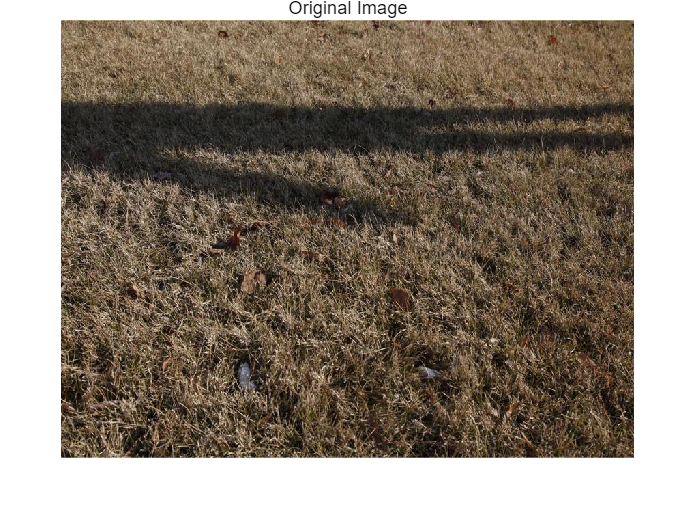

% ------------------------------------------
% 调整 Y 通道（亮度恢复）
% ------------------------------------------

% 对每个通道进行处理
for i = 1:3  % 对每个通道处理
    % 获取当前通道的图像
    img_channel = double(output_img(:,:,i));  
    
    if i == 1  % Y 通道调整
        for r = 1:rows
            for c = 1:cols
                if shadow_area(r, c, i) == 1  % 如果是阴影区域
                    % 获取阴影区域最外围的正常区域的值
                    if boundary_mask(r, c) == 1  % 如果当前像素在外围边界
                        % 获取周围非阴影区域的值
                        normal_value = img_channel(r, c);
                        
                        % 调整阴影区域的亮度
                        img_channel(r, c) = img_channel(r, c) + (normal_value - img_channel(r, c));
                    end
                end
            end
        end
    end
    
    % 更新调整后的图像通道，并转换回 uint8 类型
    output_img(:,:,i) = uint8(min(max(img_channel, 0), 255));  
end

% -----------------------------------------
% 处理 Cb 和 Cr 通道的色温调整
% -----------------------------------------

% 对阴影区域的 Cb 和 Cr 通道进行局部调整
for i = 2:3  % 对 Cb 和 Cr 通道处理
    % 获取当前通道的图像
    img_channel = double(output_img(:,:,i));  
    
    for r = 1:rows
        for c = 1:cols
            if shadow_area(r, c, i) == 1  % 如果是阴影区域
                % 获取阴影区域最外围的正常区域的值
                if boundary_mask(r, c) == 1  % 如果当前像素在外围边界
                    % 获取周围非阴影区域的值
                    normal_value = img_channel(r, c);
                    
                    % 调整阴影区域的色温
                    img_channel(r, c) = img_channel(r, c) + (normal_value - img_channel(r, c));
                end
            end
        end
    end
    
    % 更新调整后的图像通道，并转换回 uint8 类型
    output_img(:,:,i) = uint8(min(max(img_channel, 0), 255));  
end

% 显示原图和去除阴影后的图像
figure;
imshow(or_img);
title("Original Image");

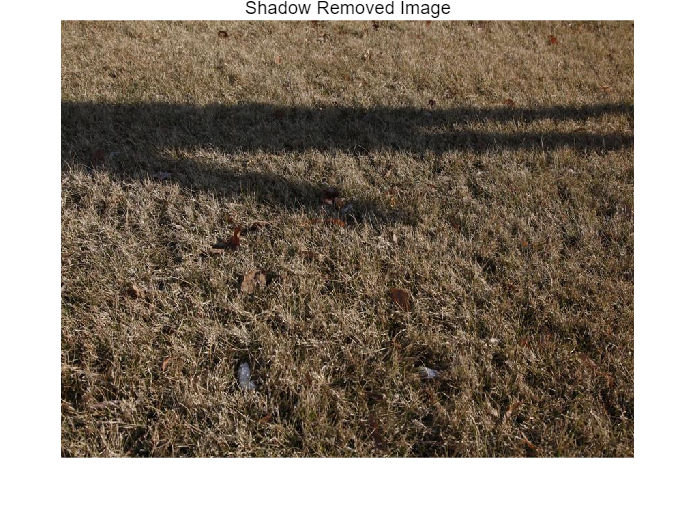

figure;
imshow(uint8(output_img));  % 将最终结果转换为 uint8
title('Shadow Removed Image');